# TD Complex loading

**A. Multi-loading **

We consider the following beam of length $4L$, of rectangular cross section (height $h$ and width $b$ ), fixed at one end, loaded by a force $P_1$ in $z=2L$ , $P_2$ in  $z=3L$ and by a moment $M_1$ (oriented along $z$) at the second end, in $z=4L$. 

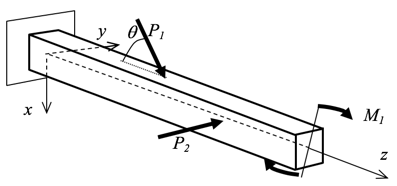

Applying the beam theory and considering that forces are applied on the neutral axis : 

(a)    Draw the diagram of the resultant force and moment.

(b)   Explain the procedure and give the components of the displacement vector of the neutral axis point located in $z=3L$.

NA: $L=1\,\mathrm m$, $h=60\,\mathrm{mm}$ , $b=40\,\mathrm{mm}$, $E=200\,\mathrm{GPa}$, the absolute values of the forces are : $P_1=2\,\mathrm{kN}$, $P_2=0.5\,\mathrm{kN}$, $M_1=1\,\mathrm{kNm}$ and $\theta=30°$ 

% méthode vectorielle


## **(a) Calculation of the reactions**

6 non nil components : 


$$R_x=-P_1\sin\theta$$



$$R_y=-P_2$$



$$R_z=-P_1\cos\theta$$



$$M_x=3L\cdot P_2$$



$$M_y=-2L\cdot P_1\sin\theta$$



$$M_z=-M_1$$


## The fundamental diagram :


$$z\in[0;2L[$$
 
$$T_x=-P_1\sin\theta$$
     
$$z\in[2L; 4L]$$
  
$$T_x=0$$



$$z\in[0;3L[$$
 
$$T_y=-P_2$$
     
$$z\in[3L; 4L]$$
  
$$T_y=0$$



$$z\in[0;2L]$$
 
$$N_z=-P_1\cos\theta$$
     
$$z\in[2L; 4L]$$
  
$$N_z=0$$



$$z\in[0;3L[$$
 
$$Mf_x=-P_2\cdot z+3L\cdot P_2$$
     
$$z\in[3L; 4L]$$
  
$$Mf_x=0$$



$$z\in[0;2L]$$
 
$$Mf_y=P_1\sin\theta\cdot z-2L\cdot P_1\sin\theta$$
     
$$z\in[2L; 4L]$$
  
$$Mf_y=0$$



$$z\in[0;4L[$$
 
$$Mt_z=-M_1$$


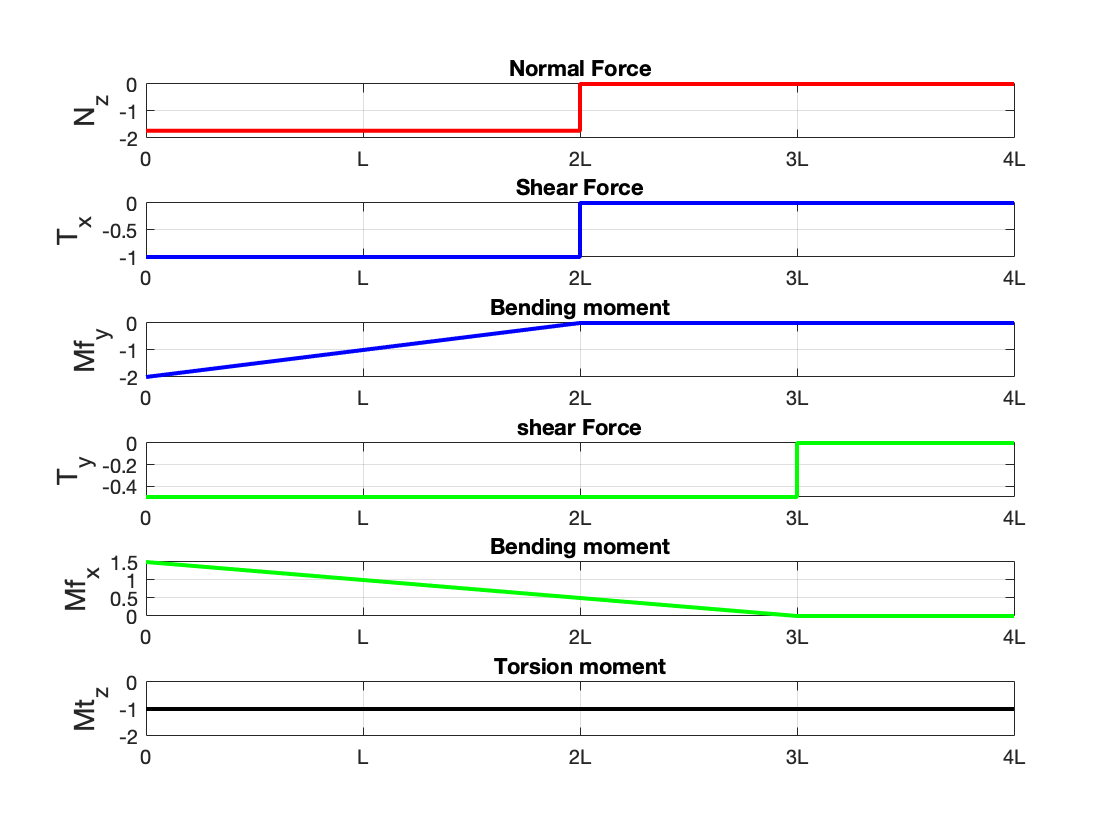

P1=2;P2=0.5; M1=1; theta=30/180*pi; L=1;
z1=0:2*L/10:2*L; z2=2*L:L/10:3*L; z3=3*L:L/10:4*L; z=[z1 z2 z3];
Tx1=-P1*sin(theta)+0*z1;Tx2=0*z2;Tx3=0*z3;Tx=[Tx1 Tx2 Tx3];
Ty1=-P2+0*z1; Ty2=-P2+0*z2; Ty3=0*z3; Ty=[Ty1 Ty2 Ty3];
Nz1=-P1*cos(theta)+0*z1; Nz2=0*z2; Nz3=0*z3; Nz=[Nz1 Nz2 Nz3];
Mx1=-P2*z1+3*L*P2; Mx2=-P2*z2+3*L*P2; Mx3=0*z3; Mfx=[Mx1 Mx2 Mx3];
My1=P1*sin(theta)*z1-2*L*P1*sin(theta); My2=0*z2; My3=0*z3; Mfy=[My1 My2 My3];
Mt1=-M1+0*z1; Mt2=-M1+0*z2; Mt3=-M1+0*z3; Mt=[Mt1 Mt2 Mt3];
figure
ax1 = subplot(6,1,1);
plot(ax1,z,Nz,'r','lineWidth',2)
title('Normal Force')
ylabel('N_z','FontSize',14);
xticks([0  L  2*L 3*L 4*L]); xticklabels({'0','L','2L','3L', '4L'})
%yticks([-2*P/3  0 P/3]); yticklabels({'-2P/3','0','P/3'})
grid on
ax2 = subplot(6,1,2);
plot(ax2,z,Tx,'b','lineWidth',2)
title('Shear Force')
ylabel('T_x','FontSize',14);
xticks([0  L  2*L 3*L 4*L]); xticklabels({'0','L','2L','3L', '4L'})
%yticks([-2*P/3  0 P/3]); yticklabels({'-2P/3','0','P/3'})
grid on
ax3 = subplot(6,1,3);
plot(ax3,z,Mfy,'b','lineWidth',2)
title('Bending moment')
ylabel('Mf_y','FontSize',14);
xticks([0  L  2*L 3*L 4*L]); xticklabels({'0','L','2L','3L', '4L'})
%yticks([-2*P/3  0 P/3]); yticklabels({'-2P/3','0','P/3'})
grid on
ax4 = subplot(6,1,4);
plot(ax4,z,Ty,'g','lineWidth',2)
title('shear Force')
ylabel('T_y','FontSize',14);
xticks([0  L  2*L 3*L 4*L]); xticklabels({'0','L','2L','3L', '4L'})
%yticks([-2*P/3  0 P/3]); yticklabels({'-2P/3','0','P/3'})
grid on
ax5 = subplot(6,1,5);
plot(ax5,z,Mfx,'g','lineWidth',2)
title('Bending moment')
ylabel('Mf_x','FontSize',14);
xticks([0  L  2*L 3*L 4*L]); xticklabels({'0','L','2L','3L', '4L'})
%yticks([-2*P/3  0 P/3]); yticklabels({'-2P/3','0','P/3'})
grid on
ax6 = subplot(6,1,6);
plot(ax6,z,Mt,'k','lineWidth',2)
title('Torsion moment')
ylabel('Mt_z','FontSize',14);
xticks([0  L  2*L 3*L 4*L]); xticklabels({'0','L','2L','3L', '4L'})
%yticks([-2*P/3  0 P/3]); yticklabels({'-2P/3','0','P/3'})
grid on

## (b) Displacement

Displacement vector $\vec u(3L)$ 3 components :

$u_y$  there is a force along $y$ in $3L$, we can therefore apply Clapeyron


$$\frac{1}{2}P_2u_y=\int_0^{4L}\frac{Mfx^2}{2EI_y}dz$$


clear all
syms P1 P2 E Ix Iy z L theta
Mfx(z)=-P2*z+3*L*P2;
uy=2/P2*1/(2*E*Ix)*int(Mfx^2,z,0,3*L)

$$uy = \frac{9\,L^{3}\,P_{2}}{\text{E}\,\mathrm{Ix}}$$

$u_x$ There is no load in 3L, one can apply Maxwell Mohr

We need to consider a beam fixed on the left and sumitted to a unit load along $x$ at 3L. 


$$r_{gx}=-1$$



$$m_{gx}=-3L$$



$$t_x(z)=-1$$



$$mf_y(z)=z-3L$$


Mfy(z)=P1*sin(theta)*z-2*L*P1*sin(theta);
mfy(z)=z-3*L;
ux=1/(E*Iy)*int(Mfy*mfy,z,0,2*L)

$$ux = \frac{14\,L^{3}\,P_{1}\,\sin\left(\theta \right)}{3\,\text{E}\,\mathrm{Iy}}$$

$u_z$ the element between $0$ to $2L$ is submitted to tensile loading :


$$\sigma=E\epsilon$$
 
$$\iff \frac{F}{S}=E\frac{\Delta L}{L_0}$$
 
$$\iff \frac{-N_z}{S}=E\frac{u_z}{2L}$$
 
$$\iff u_z=\frac{P_1\cos \theta\cdot 2L}{ES}$$


P1=2e3;P2=0.5e3; M1=1e3; theta=30/180*pi; L=1; b=40e-3; h=60e-3;
Iy=b*h^3/12; Ix=b^3*h/12; S=b*h; E=200e9;
ux=eval(ux)

ux = 0.0324

uy=eval(uy)

uy = 0.0703

uz=P1*cos(theta)*2*L/(E*S)

uz = 7.2169e-06

## B Multi beam system

We consider a system constituted of two beams AB and BC of square cross-section ($b$). The first beam AB is fixed in A and is of length $L_1$. The second beam BC of length $L_2$ is welded to the first one in B, such that the angle in B is always of 90° and a load $P$ is applied in C (see figure). We consider the axis system $(A,x,y,z)$.

1. Consider the total system AB + BC and calculate the resulting reaction force and moment in A

2. Establish the fundamental diagram of the beam AB. For this, consider AB alone and establish the different external forces applied on the beam. Note that the axis of the beam is $y$. Specify the different components of the fundamental diagram.

3. Establish the fundamental diagram of the beam BC. For this, consider BC alone and establish the different external forces applied on the beam. Note that the axis of the beam is $x$. Specify the different components of the fundamental diagram.

4. Calculate the displacement $\vec u_B$ of the point B. For this note that you can consider the beam AB alone.

 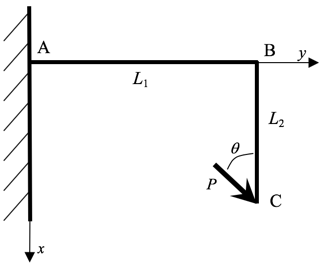

**Difficult question (to go further) : **

5. Calculate the displacement $\vec u_C$ of the point C. Note that the displacement of C is due (i) to the contribution of  the displacement of B in B’ such that $\vec u_b=\vec{BB'}$, (ii) the contribution of the global rotation of the beam BC due to the rotation in B, and (iii) to the contribution of the displacement of C if the BC beam is assumed isolated and attached in B.

6. Draw the deflected system

NA. $P=10\,\mathrm{kN}$ , $L_1=2\,\mathrm{m}$ , $L_2=1.5\,\mathrm m$, $E=200\,\mathrm {GPa}$, $\theta=30°$ , 

## 1. reactions

Three components : $R_{A,x}$ , $R_{A,y}$ , $M_{A,z}$


$$R_{A,x}=-P\cos\theta$$



$$R_{A,y}=-P\sin\theta$$


$M_{A,z}+\vec{AC}\times \vec P=0$   with $\vec{AC}\times \vec P=\left(\begin{array}{ccc}{L_2}  \\{L_1} \\0 \end{array}\right) \times \left(\begin{array}{ccc}P\cos\theta  \\P\sin\theta  \\0 \end{array}\right)$ $\iff M_{A,z}=-L_2P \sin \theta+L_1P\cos\theta$

## 2. Beam AB alone

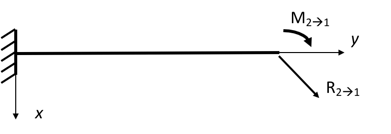

The beam is submitted in A to $\vec R_A$ and to $\vec M_A$ and in B to $\vec M_{1\rightarrow 2}$ and $\vec R_{1\rightarrow 2}$

we have : $\vec R_{2\rightarrow 1}=\vec P$ and $\vec M_{2\rightarrow 1}=\vec {BC}\times \vec P$   with $\vec {BC}\times \vec P=\left(\begin{array}{ccc}{L_2}  \\0 \\0 \end{array}\right) \times \left(\begin{array}{ccc}P\cos\theta  \\P\sin\theta  \\0 \end{array}\right)$

so that $M_{2\rightarrow 1}=L_2P\sin\theta$.


$$N_y(y)=-P\sin\theta$$



$$T_x(y)=-P\cos \theta$$



$$Mf_z(y)=-P\cos \theta \cdot y+L_1P\cos \theta-L_2P\sin\theta$$


## 3. Beam BC alone

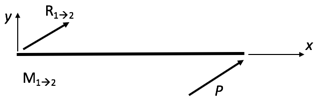

$\vec R_{1\rightarrow 2}=-\vec R_{2\rightarrow 1}$  and   $\vec M_{1\rightarrow 2}=-\vec M_{2\rightarrow 1}$


$$N_x(x)=-P\cos\theta$$



$$T_y(x)=-P\sin\theta$$



$$Mf_z(x)=P\sin\theta\cdot x-L_2P\sin\theta$$


## 4. displacement in B

Two components : $u_x$ and $u_y$

The second one $u_y$ corresponds to some tension :


$$\frac{F}{S}=E\frac{u_y}{L_1}$$
 
$$\iff u_y=\frac{P\sin\theta L_1}{ES}$$


For the first one $u_x$ one can apply Maxwell mohr, considering a beam fixed on the left of axis $x$, on which we apply a unity load along $y$. The reactions are $r_g=-1$ and $m_g=L_1$

the fundamental diagram is therefore :


$$t_x(y)=-1$$



$$mf_z(y)=-y+L_1$$


the displacemnt is therefore : $u_x=\frac{1}{EI_z}\int_0^{L_1}Mf_zmf_zdy$

clear all
syms theta L1 L2 P
P1=[P*cos(theta);P*sin(theta);0]

$$P1 = \left(\begin{array}{c} P\,\cos\left(\theta \right)\\ P\,\sin\left(\theta \right)\\ 0 \end{array}\right)$$

RA=-P1

$$RA = \left(\begin{array}{c} -P\,\cos\left(\theta \right)\\ -P\,\sin\left(\theta \right)\\ 0 \end{array}\right)$$

vAC=[L2;L1;0];
MA=-cross(vAC,P1)

$$MA = \left(\begin{array}{c} 0\\ 0\\ L_{1}\,P\,\cos\left(\theta \right)-L_{2}\,P\,\sin\left(\theta \right) \end{array}\right)$$

clear all
syms P theta y L1 L2 E I b
Mfz(y)=-P*cos(theta)*y+L1*P*cos(theta)-L2*P*sin(theta);
mfz(y)=-y+L1;
ux=1/(E*I)*int(Mfz*mfz,y,0,L1)

$$ux = \frac{{L_{1}}^{2}\,P\,\left(2\,L_{1}\,\cos\left(\theta \right)-3\,L_{2}\,\sin\left(\theta \right)\right)}{6\,\text{E}\,\text{I}}$$

uy=P*sin(theta)*L1/E/b^2;
ux2=2/(P*cos(theta))*int(Mfz^2,y,0,L1)/(2*E*I);
E=200e9; b=50e-3;I=b^4/12; P=10e3; L1=2; L2=1.5; theta=30*pi/180;

dux3(y)=1/(E*I)*int(Mfz,y);
ux3(y)=int(dux3,y);
eval(ux3(L1))

ans = 0.0777

eval(ux)

ans = 0.0777

eval(ux2)

ans = 0.0584

Let's try to calcule the displacement function :

$\frac{d^2x}{dy^2}=\frac{Mf_z}{EI_z}$ and integrating twice :

% deflexion L1 beam
dxdy(y)=1/(E*I)*int(Mfz,y)

$$dxdy(y) = -\frac{5666839779443573\,P\,y\,\left(2\,L_{2}\,\sin\left(\theta \right)-2\,L_{1}\,\cos\left(\theta \right)+y\,\cos\left(\theta \right)\right)}{1180591620717411303424}$$

x(y)=int(dxdy,y)

$$x(y) = -\frac{5666839779443573\,P\,y^{2}\,\left(3\,L_{2}\,\sin\left(\theta \right)-3\,L_{1}\,\cos\left(\theta \right)+y\,\cos\left(\theta \right)\right)}{3541774862152233910272}$$

P=10e3; theta=30/180*pi; L1=2; L2=1.5; E=200e9; b=50e-3; I=b^4/12;
ux_B=eval(ux)

ux_B = 0.0777

uy_B=eval(uy)

uy_B = 2.0000e-05

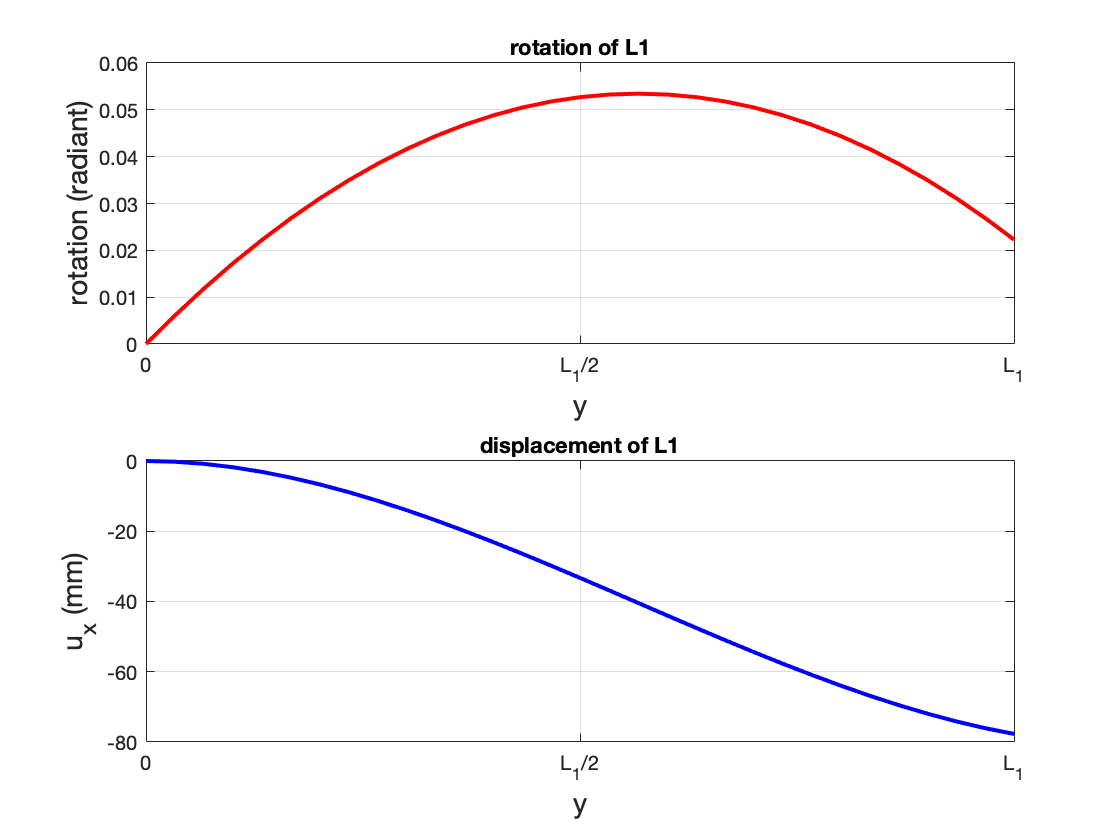

%L1 beam
y=0:L1/30:L1;
du=eval(dxdy(y));
u=eval(x(y));
figure
ax1 = subplot(2,1,1);
plot(ax1,y,du,'r','lineWidth',2)
title('rotation of L1')
xlabel('y','FontSize',14);
ylabel('rotation (radiant)','FontSize',14);
xticks([0  L1/2  L1]); xticklabels({'0','L_1/2','L_1'})
grid on
ax2 = subplot(2,1,2);
plot(ax2,y,-u*1e3,'b','lineWidth',2)
title('displacement of L1')
xlabel('y','FontSize',14);
ylabel('u_x (mm)','FontSize',14);
xticks([0  L1/2  L1]); xticklabels({'0','L_1/2','L_1'})
grid on

plot of the full displacement :

clear all
syms P theta y x L1 L2 E I b
% Beam L1
Mf1z(y)=-P*cos(theta)*y+L1*P*cos(theta)-L2*P*sin(theta);
dxdy1(y)=1/(E*I)*int(Mf1z,y);
ux1(y)=int(dxdy1,y)  %depl x L1

$$ux1(y) = -\frac{P\,y^{2}\,\left(3\,L_{2}\,\sin\left(\theta \right)-3\,L_{1}\,\cos\left(\theta \right)+y\,\cos\left(\theta \right)\right)}{6\,\text{E}\,\text{I}}$$

uy1_B=P*sin(theta)*L1/E/b^2;

% Beam L2
Mf2z(x)=P*sin(theta)*x-L2*P*sin(theta)

$$Mf2z(x) = P\,x\,\sin\left(\theta \right)-L_{2}\,P\,\sin\left(\theta \right)$$

dxdy2(x)=1/(E*I)*int(Mf2z,x)

$$dxdy2(x) = -\frac{P\,x\,\sin\left(\theta \right)\,\left(2\,L_{2}-x\right)}{2\,\text{E}\,\text{I}}$$

uy2(x)=int(dxdy2,x) %depl y L2

$$uy2(x) = -\frac{P\,x^{2}\,\sin\left(\theta \right)\,\left(3\,L_{2}-x\right)}{6\,\text{E}\,\text{I}}$$


%plot of the curves
P=10000; theta=30/180*pi; L1=2; L2=1.5; E=200e9; b=50e-3; I=b^4/12;
coef=3; % factor to plot the displacement to enlarge them

t_B=eval(dxdy1(L1))

t_B = 0.0223

ux1_B=eval(ux1(L1))

ux1_B = 0.0777

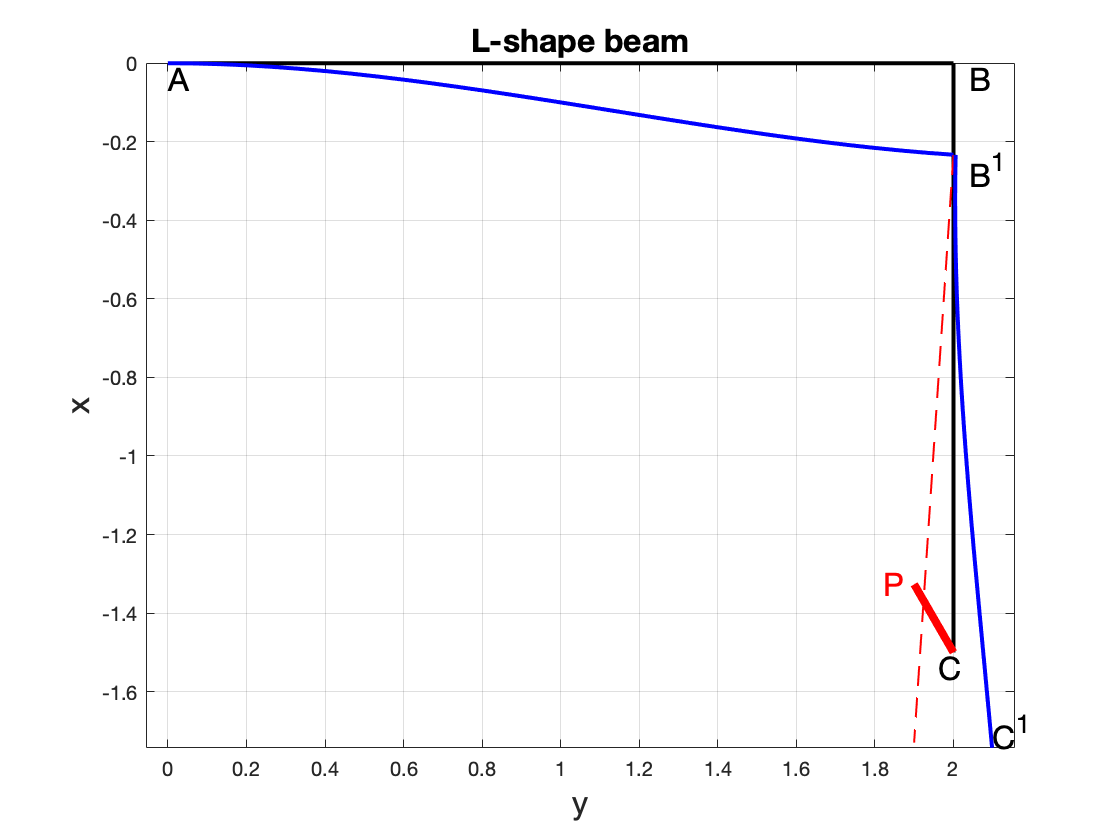


% plot initial situation
y1=0:L1/30:L1;
x1=0*y1;
x2=0:L2/30:L2;
y2=0*x2+L1;
figure
plot(y1,-x1,'-k','lineWidth',2) % L1 beam initial
hold on
plot(y2,-x2,'-k','lineWidth',2) % L2 beam initial

x1=eval(ux1(y1))*coef;
plot(y1,-x1,'-b','lineWidth',2) % L1 beam loaded

y3=L1-x2*sin(t_B*coef);
x3=x2*cos(t_B*coef)+ux1_B*coef;
plot(y3,-x3,'--r','lineWidth',1) % L2 beam with only rotation

x4=x3-eval(uy2(x3)*coef*sin(t_B*coef));
y4=y3-eval(uy2(x3)*coef*cos(t_B*coef));
plot(y4,-x4,'-b','lineWidth',2) % L2 beam loaded
% reprsentation of the load
F=L1/10; Ax=L1; Ay=-L2 ;Bx=Ax-F*sin(theta) ;By=Ay+F*cos(theta);
A=[Ax Bx]; B=[Ay By];
plot(A,B,'-r','lineWidth',4)

hold off
axis equal
grid on
xlabel('y','FontSize',16)
ylabel('x','FontSize',16)
title('L-shape beam','FontSize',16)
dev=L1/50; %shift for text
text(0,0-dev,'A','FontSize',16)
text(L1+dev,0-dev,'B','FontSize',16)
text(L1-dev,-L2-dev,'C','FontSize',16)
text(L1+dev,-ux1_B*coef-dev,'B^1','FontSize',16)
text(max(y4),-max(x4)+dev,'C^1','FontSize',16)
text(Bx-2*dev,By,'P','color','r','FontSize',16)